# Изучение спектров звёзд

## Объявление постоянных величин

close all
clear variables
speedOfLight = 299792.458 %км/с

speedOfLight = 2.9979e+05

lambdaPr = 656.28 % нм

lambdaPr = 656.2800

## Импорт данных

spectra = importdata('spectra.csv')

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


starNames = importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


lambdaStart = importdata('lambda_start.csv')

lambdaStart = 630.0200

lambdaDelta = importdata('lambda_delta.csv')

lambdaDelta = 0.1400

## Определение количества изучаемых звёзд

n_stars = size(starNames,1)

n_stars = 7

## Определение диапазона длин волн

n_obs = size(spectra,1)

n_obs = 357

lambdaEnd = lambdaStart + (n_obs - 1)*lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart:lambdaDelta:lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800


## Расчёт скорости удаления звёзд от Земли

i = 1;
speed = zeros(n_stars, 1);
while i <= n_stars
    s = spectra(:,i);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    speed(i,1) = ((lambdaHa/lambdaPr) - 1) * speedOfLight;
    i = i + 1;
end
speed

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


movaway = starNames(speed>0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


## Построение графиков

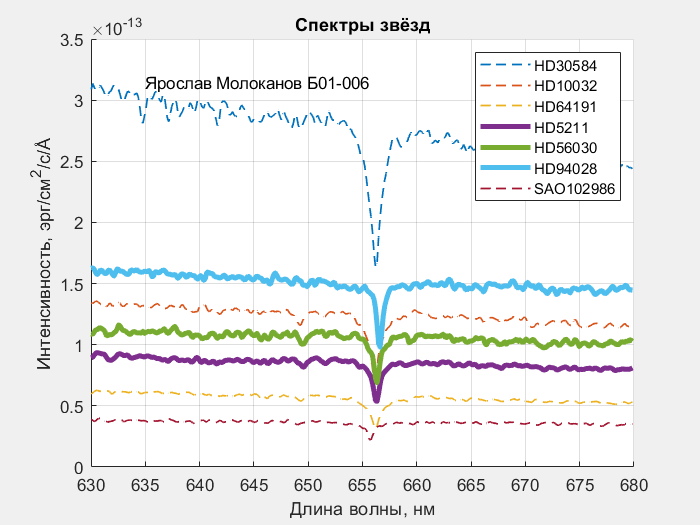

fg = figure;
set(fg, 'Visible', 'on');
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title({'Спектры звёзд'})
grid on
hold on
for i = 1:1:n_stars
    s = spectra(:,i);
    if speed(i,1) < 0
       plot(lambda, s, "--", 'LineWidth', 1)
    end
    if speed(i,1) > 0
        plot(lambda, s, 'LineWidth', 3)
    end
end
legend(starNames, 'Location', 'northeast')
text(0.1, 0.9,'Ярослав Молоканов Б01-006','Units', 'normalized')
hold off
saveas(fg, 'spectra.png')